# Laboratorio - Analisis y simulacion de robot industrial 

## 1.Localizacion de ruta 

A partir de las rutas sugeridas se seleccionó la ruta rectangular con esquinas curvas, de acuerdo al grafico de la siguiente figura se crea la trayectoria a trozos en un plano XY que posteriormente sera rotado y transladado al espacio de trabajo del robot.

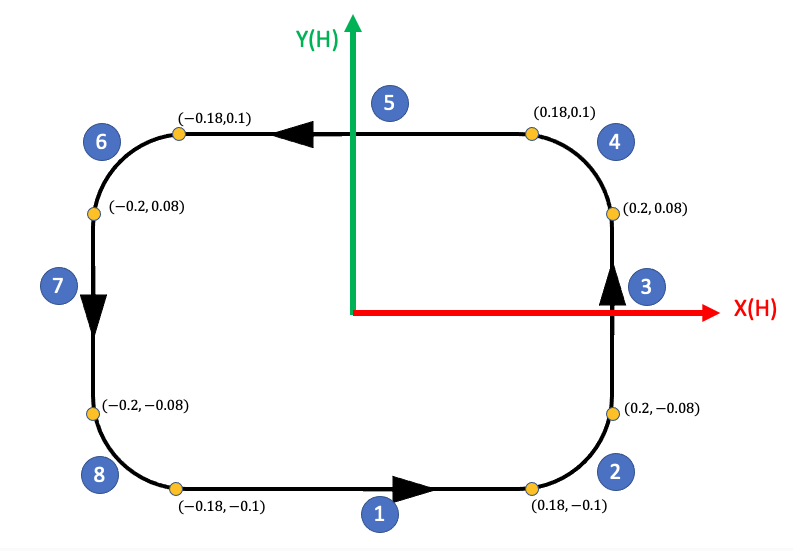

clc;clear;close all

Como se ve en la figura anterior las coordenadas de la trayectoria son función del alcance horizontal del robot. Para el robot que se analizará en el presente trabajo el alcance horizontal (H) es igual a 700mm. Para poder escalar la trayectoria basta con multiplicar los parámetros de la misma por el alcance H como se muestra a continuación.

H=700;
a = 0.18*H; %distancia en x
b = 0.1*H;  %distancia en y
c = 0.08*H; %centro en y de los semicirculos
r = 0.02*H; %radio 

La trayectoria fue generada por segmentos de curvas y rectas concatenados entre sí comenzando en la coordenada (-0.18,-0.1) en sentido horario como se muestra a continuación.

%%Ruta 1
x = -a:0.01:a;
len = size(x);
y = -b*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = R1;

figure()
plot(x,y);
hold on

%%Ruta 2
t = 3*pi/2:pi/20:2*pi;
x = r*cos(t)+a;
y = r*sin(t)-c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);
%%Ruta 3
y = -c:0.01:c;
len = size(y);
x = (a+r)*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 4
t = 0:pi/20:pi/2;
x = r*cos(t)+a;
y = r*sin(t)+c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 5
x = -a:0.01:a;
len = size(x);
y = b*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 6
t = pi/2:pi/20:pi;
x = r*cos(t)-a;
y = r*sin(t)+c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 7
y = -c:0.01:c;
len = size(y);
x = -(a+r)*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 8
t = pi:pi/20:3*pi/2;
x = r*cos(t)-a;
y = r*sin(t)-c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];

traye = [traye,R1];
plot(x,y);

hold off

La trayectoria elegida debe realizarse en el plano asignado para este ejercicio. En este caso particular el plano debe ser perpendicular al vector [-1,0,1]. Para rotar la trayectoria se crea una matriz de rotación la cual permita obtener la orientación deseada.

%Matriz de Rotacion
R = [1/sqrt(2),0,-1/sqrt(2);
     0        ,1,0         ;
     1/sqrt(2),0, 1/sqrt(2)];

Finalmente se dejan enunciados los parámetros de desplazamiento de la trayectoria para posteriormente poder ubicarla en el espacio diestro del robot como se solicitó.

% Desplazamiento
x = 0;
y = 0;
z = 0;

%% Rotacion y dezplazamiento de la trayectoria

len = size(traye);
for i = 1:len(2)
    traye(1:3,i) = R*traye(1:3,i);
end

traye(1,:) = x + traye(1,:);
traye(2,:) = y + traye(2,:);
traye(3,:) = z + traye(3,:);

figure
plot3(traye(1,:),traye(2,:),traye(3,:))
grid on
view([142 47])

## 2.Caracteristicas y modelo del robot

- Imagen del robot. https://www.robots.com/robots/fanuc-lr-mate-200ib

http://geek.nmt.edu/~bruder/final_project_files/Fanuc%20LR%20Mate_200ib_200ib_3l.pdf

			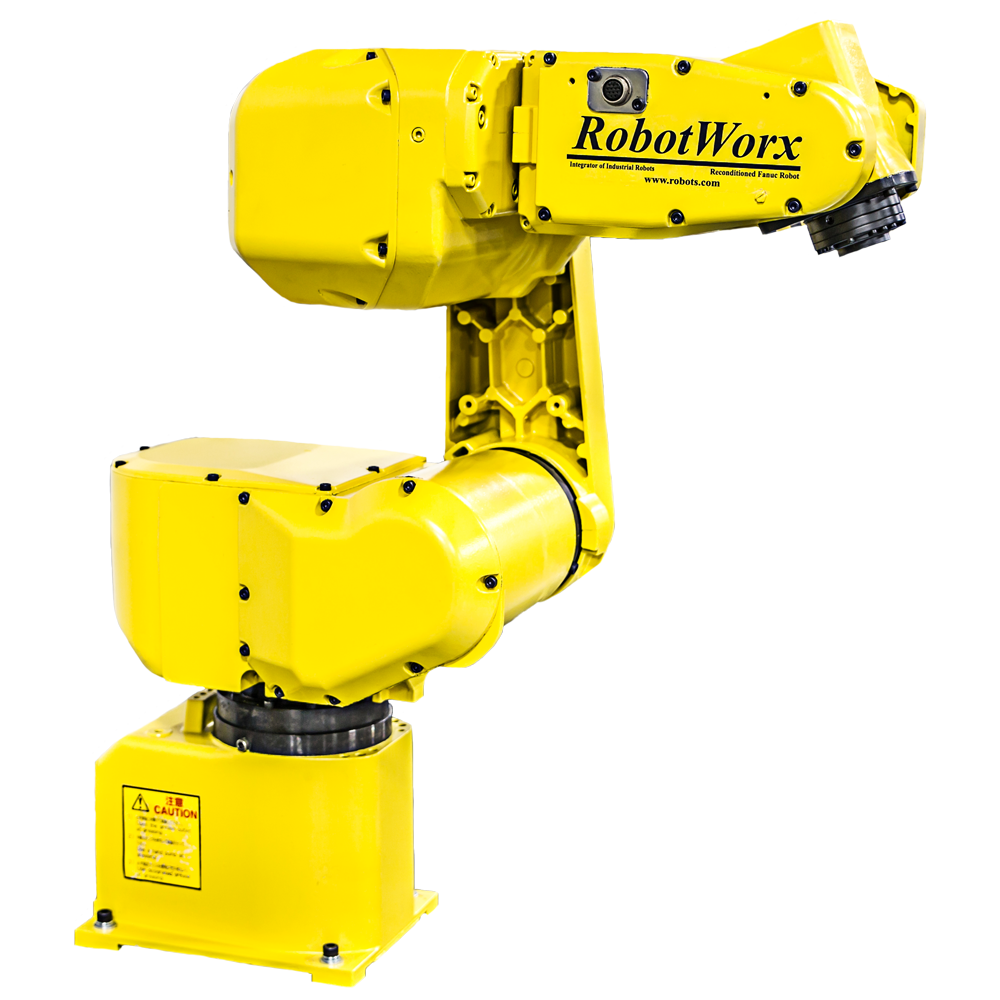		

2. Capacidad de carga = 5 kg.

3. Alcance vertical y horizontal. 

H-Reach: 700 mm

V-Reach-Max: 550 mm			

4. Repetibilidad. = **± 0.04mm**

5. Grafica(s) de espacio alcanzable.

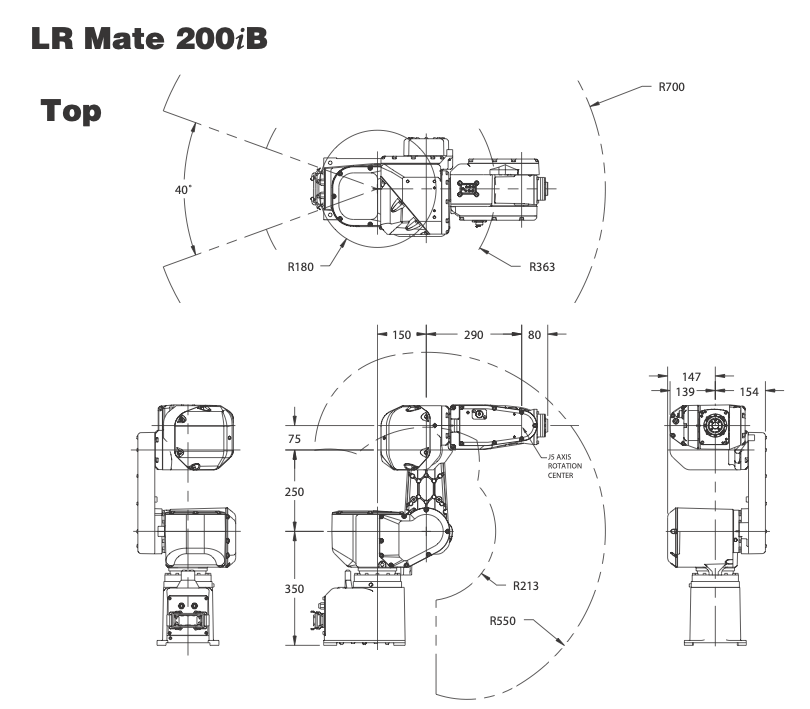

6. Tabla de parametros DH.

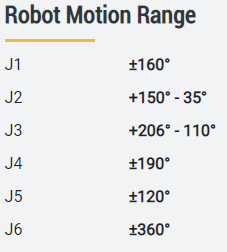

7. Que software utiliza el fabricante para diseño de celdas o programacion. 

FANUC ROBOGUIDE SIMULATION SOFTWARE

## PARTE 2	

### 6. Iniciando

En la figura que se muestra a continuación se ubicaron los sistemas coordenados sobre las articulaciones del robot para establecer el modelo DH módificado del mismo utilizando los objetos Link y SerialLink del Toolbox de Peter Corke.

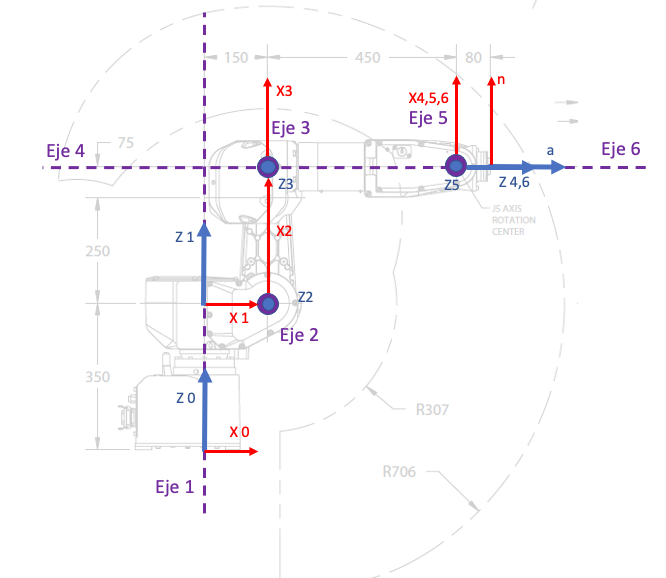

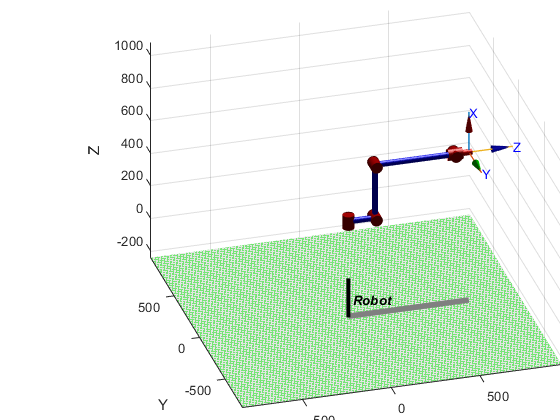

l0 = 350; l1 = 150; l2 = 250+75; l3 = 450;l4 = 80;
ws= [-70 80 -70 80 -20 90]*12;
plot_options = {'workspace',ws,'scale',0.5,'view',[-100 30], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L(1) = Link('revolute'  ,'alpha',     0,'a',   0, 'd',  l0,'offset',   0, 'qlim',        [-8*pi/9 8*pi/9],   'modified');
L(2) = Link('revolute'  ,'alpha',  pi/2,'a',  l1, 'd',   0,'offset',pi/2, 'qlim',       [-7*pi/36 5*pi/6],   'modified');
L(3) = Link('revolute'  ,'alpha',     0,'a',  l2, 'd',   0,'offset',   0, 'qlim',   [-11*pi/18 103*pi/90],   'modified');
L(4) = Link('revolute'  ,'alpha',  pi/2,'a',   0, 'd',  l3,'offset',   0, 'qlim',    [-19*pi/18 19*pi/18],   'modified');
L(5) = Link('revolute'  ,'alpha', -pi/2,'a',   0, 'd',   0,'offset',   0, 'qlim',        [-2*pi/3 2*pi/3],   'modified');
L(6) = Link('revolute'  ,'alpha',  pi/2,'a',   0, 'd',   0,'offset',   0, 'qlim',            [-2*pi 2*pi],   'modified');

Robot = SerialLink(L,'name','Robot','plotopt',plot_options);
Robot.tool = [1,0,0,0;
              0,1,0,0;
              0,0,1,l4;
              0,0,0,1];
Robot.teach()
view([-16 28])

MTH01 = L(1).A(0);
MTH12 = L(2).A(0);
MTH23 = L(3).A(0);
MTH34 = L(4).A(0);
MTH45 = L(5).A(0);
MTH56 = L(6).A(0);
MTH6T = Robot.tool;

Posteriormente, utilizando el Robotics Systems Toolbox se crean los eslabones del robot con sus respectivas articulaciones para posteriormente ensamblarlos entre sí en un árbol de cuerpos rigidos como se ilustra a continuación.

robotRST = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt1.HomePosition = 0;
tform1 = trvec2tform([0 0 l0]);
setFixedTransform(jnt1,tform1);
body1.Joint = jnt1;

addBody(robotRST,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.HomePosition = 0;
tform2 = trvec2tform([l1 0 0])*eul2tform([0 -pi/2 pi/2]);
setFixedTransform(jnt2,tform2);
body2.Joint = jnt2;

addBody(robotRST,body2,'body1')

body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt3.HomePosition = 0;
tform3 = trvec2tform([l2 0 0]);
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;

addBody(robotRST,body3,'body2')

body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt4.HomePosition = 0;
tform4 = trvec2tform([0 -l3 0])*eul2tform([0 0 pi/2]);
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;

addBody(robotRST,body4,'body3')

body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt5.HomePosition = 0;
tform5 = eul2tform([0 0 -pi/2]);
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;

addBody(robotRST,body5,'body4')

body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');
jnt6.HomePosition = 0;
tform6 = eul2tform([0 0 pi/2]);
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;

addBody(robotRST,body6,'body5')

bodyEndEffector = rigidBody('endeffector');
tformEfec = trvec2tform([0 0 l4]);
setFixedTransform(bodyEndEffector.Joint,tformEfec);
addBody(robotRST,bodyEndEffector,'body6');

figure()
show(robotRST)

ans =   Axes (Primary) with properties:

             XLim: [-960.5000 960.5000]
             YLim: [-960.5000 960.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


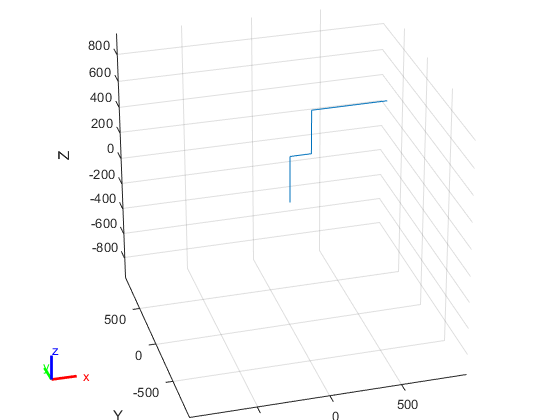

view([-16 28])

Comparando los resultados obtenidos con ambos Toolbox para hallar la posición del efector final respecto a la base en la configuración de home, se puede ver que los resultados son consistentes entre ambos métodos.

MTH0T = MTH01*MTH12*MTH23*MTH34*MTH45*MTH56*MTH6T

MTH0T =     0.0000   -0.0000    1.0000  680.0000
    0.0000   -1.0000   -0.0000   -0.0000
    1.0000    0.0000   -0.0000  675.0000
         0         0         0    1.0000


config = homeConfiguration(robotRST);
tform = getTransform(robotRST,config,'endeffector','base')

tform =     0.0000   -0.0000    1.0000  680.0000
         0   -1.0000   -0.0000   -0.0000
    1.0000    0.0000   -0.0000  675.0000
         0         0         0    1.0000


Utilizando la hoja técnica del controlador R-J3iB se puede ver que se tiene la siguiente configuración para realizar las pruebas de calibración del robot utilizando cinemática directa.

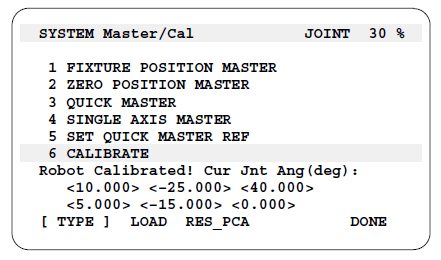

A continuación se procede a probar este punto de calibración utilizando los métodos de cinemática directa de cada uno de los Toolbox trabajdos.

q = deg2rad([10,-25,40,5,-15,0]);
Robot.fkine(q)

ans =     0.0156    0.1952    0.9806  789.4997
   -0.0827   -0.9771    0.1958  141.0425
    0.9964   -0.0842    0.0010  761.0947
         0         0         0    1.0000


c1 = num2cell(q);
s = homeConfiguration(robotRST);
[s.JointPosition] = c1{:};
tform = getTransform(robotRST,s,'endeffector','base')

tform =     0.0156    0.1952    0.9806  789.4997
   -0.0827   -0.9771    0.1958  141.0425
    0.9964   -0.0842    0.0010  761.0947
         0         0         0    1.0000


### 7. Modelo geometrico directo			

- Halle el modelo geometrico directo de su robot asignado usando MTH.

Hallando las MTH de cada eslabón de manera simbólica se procede a multiplicarlas entre sí para obtener la matriz MTH desde la base hasta el efector final en terminos de los valores articulares del robot.

threshold = 1e-8;
syms theta1 theta2 theta3 theta4 theta5 theta6
MTH_01 = mapSymType(L(1).A(theta1),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_12 = mapSymType(L(2).A(theta2),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_23 = mapSymType(L(3).A(theta3),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_34 = mapSymType(L(4).A(theta4),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_45 = mapSymType(L(5).A(theta5),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_56 = mapSymType(L(6).A(theta6),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_6T = Robot.tool;
MTH_0T = MTH_01*MTH_12*MTH_23*MTH_34*MTH_45*MTH_56*MTH_6T;
MTH_0T = simplify(MTH_0T)

2. Haciendo uso del modelo cinematico directo obtenga los valores de posicion y de orientacion en coordenadas generalizadas del efector final de su robot asignado para los siguientes valores articulares: 

Teniendo en cuenta que se desea obtener la orientación del efector final en ángulos fijos $\left(\phi \left(\textrm{roll}\right),\theta \;\left(\textrm{pitch}\right),\psi \;\left(\textrm{yaw}\right)\right)$ se tiene que el modelo de la MTH del efector final respecto a la base es el siguiente:

syms phi theta psi x y z

MTH_Robot = transl(x,y,z)*trotz(psi)*troty(theta)*trotx(phi)

$$MTH\_Robot = \left(\begin{array}{cccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & x\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & y\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & z\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Con los elementos de la matriz anterior es posible despejar las variables de posición y orientación del efector final así:

x = simplify(MTH_0T(1,4))

$$x = 150\,\cos\left(\theta_{1}\right)-325\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-450\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+80\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)+450\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)+80\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{5}\right)-80\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-80\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{5}\right)-80\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{5}\right)$$

y = simplify(MTH_0T(2,4))

$$y = 150\,\sin\left(\theta_{1}\right)-325\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-80\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)-450\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+450\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)+80\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)-80\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-80\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{5}\right)-80\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{5}\right)$$

z = simplify(MTH_0T(3,4))

$$z = 325\,\cos\left(\theta_{2}\right)+450\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+450\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)+80\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{3}\right)+80\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{2}\right)+80\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)-80\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{5}\right)+350$$

theta = simplify(asin(-MTH_0T(3,1)))

$$theta = \mathrm{asin}\left(\cos\left(\theta_{6}\right)\,\left(\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{5}\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\right)+\cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)\right)$$

phi = simplify(atan2(MTH_0T(3,2),MTH_0T(3,3)))

$$phi = \text{atan2}\left(\sin\left(\theta_{6}\right)\,\left(\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{5}\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right),\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{5}\right)+\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)\right)$$

psi = atan2(MTH_0T(2,1),MTH_0T(1,1))

$$psi = \text{atan2}\left(\sin\left(\theta_{6}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)\right)-\cos\left(\theta_{6}\right)\,\left(\cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{5}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right),\sin\left(\theta_{6}\right)\,\left(\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)\right)-\cos\left(\theta_{6}\right)\,\left(\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{5}\right)-\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{2}\right)\right)\right)$$

De esta manera, basta con hallar el valor númerico de la matriz MTH del efector final a la base con los valores articulares dados y hallar los valores de posición y orientación en cada configuración.

q1 = [0.5,0.2,0.4,0.5,0,1.5];
q2 = [-pi/2,0.3,0,pi/2,0.4,1.2];
q3 = [0,1,-0.5,2,1,0.5];
q4 = [-1,-0.3,-pi/5,0.4,0.2,1];

MTH_Robot = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q1));
x = MTH_Robot(1,4);
y = MTH_Robot(2,4);
z = MTH_Robot(3,4);
theta = asin(-MTH_Robot(3,1));
phi = atan2(MTH_Robot(3,2),MTH_Robot(3,3));
psi = atan2(MTH_Robot(2,1),MTH_Robot(1,1));
X= [x;y;z;phi;theta;psi]

X =   458.8531
  250.6726
  967.7821
   -0.9258
    0.3506
   -0.8179


MTH_Robot = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q2));
x = MTH_Robot(1,4);
y = MTH_Robot(2,4);
z = MTH_Robot(3,4);
theta = asin(-MTH_Robot(3,1));
phi = atan2(MTH_Robot(3,2),MTH_Robot(3,3));
psi = atan2(MTH_Robot(2,1),MTH_Robot(1,1));
X= [x;y;z;phi;theta;psi]

X =   -31.1535
 -554.2512
  815.2438
   -0.7204
    1.2002
   -2.7428


MTH_Robot = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q3));
x = MTH_Robot(1,4);
y = MTH_Robot(2,4);
z = MTH_Robot(3,4);
theta = asin(-MTH_Robot(3,1));
phi = atan2(MTH_Robot(3,2),MTH_Robot(3,3));
psi = atan2(MTH_Robot(2,1),MTH_Robot(1,1));
X= [x;y;z;phi;theta;psi]

X =   322.7975
  -61.2118
  737.4779
   -1.6874
    1.1427
   -2.5496


MTH_Robot = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q4));	
x = MTH_Robot(1,4);
y = MTH_Robot(2,4);
z = MTH_Robot(3,4);
theta = asin(-MTH_Robot(3,1));
phi = atan2(MTH_Robot(3,2),MTH_Robot(3,3));
psi = atan2(MTH_Robot(2,1),MTH_Robot(1,1));
X= [x;y;z;phi;theta;psi]

X =   305.1279
 -486.6637
  246.2073
   -2.3274
   -0.1829
   -2.5058


3. Haga uso de las funciones de cinematica directa de ambos toolboxes y compruebe los resultados anteriores. 

**Peter corke**

PMTH=Robot.fkine(q1);
X=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]

X =   458.8531
  250.6726
  967.7821
   -0.9258
    0.3506
   -0.8179


PMTH=Robot.fkine(q2);
X=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]

X =   -31.1535
 -554.2512
  815.2438
   -0.7204
    1.2002
   -2.7428


PMTH=Robot.fkine(q3);
X=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]

X =   322.7975
  -61.2118
  737.4779
   -1.6874
    1.1427
   -2.5496


PMTH=Robot.fkine(q4);
X=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]

X =   305.1279
 -486.6637
  246.2073
   -2.3274
   -0.1829
   -2.5058


**RST**

c1 = num2cell(q1);
c2 = num2cell(q2);
c3 = num2cell(q3);
c4 = num2cell(q4);
s = homeConfiguration(robotRST);
[s.JointPosition] = c1{:};
tform = getTransform(robotRST,s,'endeffector','base');
X=[tform2trvec(tform)';flip(tform2eul(tform)')] 

X =   458.8531
  250.6726
  967.7821
   -0.9258
    0.3506
   -0.8179


[s.JointPosition] = c2{:};
tform = getTransform(robotRST,s,'endeffector','base');
X=[tform2trvec(tform)';flip(tform2eul(tform)')] 

X =   -31.1535
 -554.2512
  815.2438
   -0.7204
    1.2002
   -2.7428


[s.JointPosition] = c3{:};
tform = getTransform(robotRST,s,'endeffector','base');
X=[tform2trvec(tform)';flip(tform2eul(tform)')] 

X =   322.7975
  -61.2118
  737.4779
   -1.6874
    1.1427
   -2.5496


[s.JointPosition] = c4{:};
tform = getTransform(robotRST,s,'endeffector','base');
X=[tform2trvec(tform)';flip(tform2eul(tform)')] 

X =   305.1279
 -486.6637
  246.2073
   -2.3274
   -0.1829
   -2.5058


4. Compare los metodos. 

Como se mostró anteriormente se llega a los mismos resultados utilizando los tres métodos implementados de cinemática directa, es importante mencionar que para el caso del Toolbox de Peter Corke se debe configurar la convención de las rotaciones en angulos fijos con el valor 'zyx'. Esta es la configuración por defecto en el Robotics Systems Toolbox, por lo que se omite este parámetro. En las funciones de ambos Toolbox se debe invertir el orden del vector para poder expresar la orientación primero respecto al eje "x", luego el eje "y" y finalmente el eje "z".					

5. Elija uno de los metodos anteriormente usados y desarrolle una GUI que permita mover cada articulacion mediante controles tipo Slider, visualizar el robot y la posicion del efector final. 

6. En el informe incluya capturas de pantalla verificando las posiciones EF y las articulaciones. 

## 8. Modelo Geometrico Inverso 			

- Determine el modelo geometrico inverso del robot asignado haciendo uso de la metodologıa explicada en clase. 

Utilizando la aproximacion de desacople cinematico, se realizan los siguiente esquemas para determinar la cinematica inversa de la posicion.

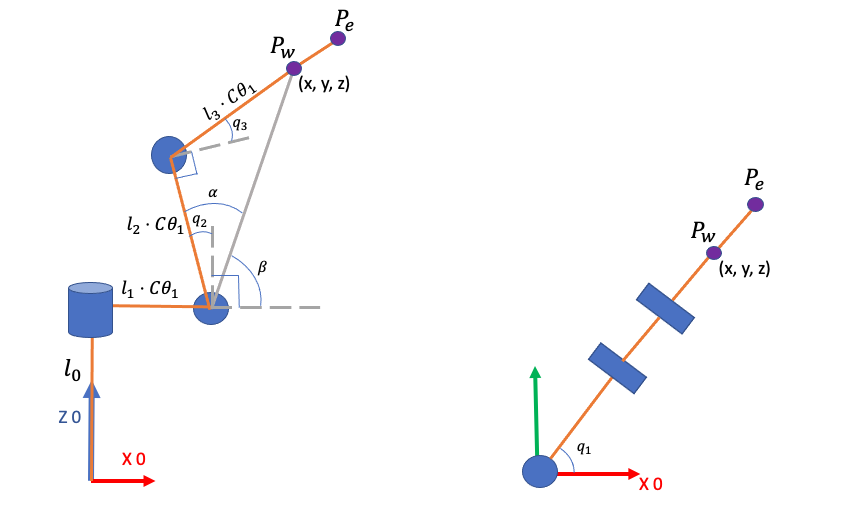

La posicion de la articulacion 1 se puede hallar facilemente usando la vista del plano XY:

 
$$\theta_1 = atan2(y,x)$$
    

Ahora desde el pano ZX, a partir de la vista proyectada del mecanismo se halla el vector la distancia $r$:


$$r^2 = (x-l_1 \cdot C\theta_1 )^2 + (z-l_0)^2$$


Usando la ley del coseno se halla la posicion de la articulacion 3 ($\theta_3$):


$$cos(\theta_3 + \pi/2) = \frac{ (l_3\cdot C\theta_1)^2 + (l_2\cdot C\theta_1)^2 }{-2(l_3\cdot C\theta_1)(l_2\cdot C\theta_1)}$$



$$sen(\theta_3) = \frac{l_3^2 + l_2^2}{2l_2l_3}$$


Para hallar la poscion de la articulacion 2  ($\theta_2
$) es necesario hallar los angulos $\alpha$ y $\beta$:


$$cos(\alpha) = \frac{(l_2 \cdot C\theta_1)^2 + r^2}{-2(l_2\cdot C\theta_1)r}$$



$$\beta = atan2( z - l_0, x-C\theta_1 \cdot l_1)$$


La posicion de la articulacion 2 ($\theta_2$) es:


$$\theta_2 = \alpha + \beta -\frac{\pi}{2}$$
 

2. En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones. 

3. Haga uso de las funciones del RVC para hallar la cinematica inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox explique: 

¿Cual es la diferencia entre estas funciones? 

¿Cual debe usar para su robot y por que? (Revise la documentacion del Toolbox)

4. Haga uso del RST para hallar la cinematica inversa de su robot asignado y compruebe los resultados anteriores. Compare los metodos. 

5. Calcule la configuracion del robot para las siguientes posturas de la herramienta. Proponga 4 posturas (x,y,z,roll,pitch,yaw)′ que esten dentro del espacio de trabajo y determine la configuracion del manipulador y complete la tabla 2. 

Considerando que para que el robot ejecute los movimientos, se desea establecer una relación entre las velocidades del efector �final y las articulaciones.

    1. Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores númericos, NO simbólico) en función de los ángulos de articulación.

Para obtener la matriz jacobiana de forma numérica se utilizaron las MTH que representan al robot en la posición de home, donde todas las articulaciónes tienen el valor de 0.

MTH02 = MTH01*MTH12;
MTH03 = MTH02*MTH23;
MTH04 = MTH03*MTH34;
MTH05 = MTH04*MTH45;
MTH06 = MTH05*MTH56;
J1 = [cross(MTH01(1:3,3),(MTH0T(1:3,4)-MTH01(1:3,4)));MTH01(1:3,3)];
J2 = [cross(MTH02(1:3,3),(MTH0T(1:3,4)-MTH02(1:3,4)));MTH02(1:3,3)];
J3 = [cross(MTH03(1:3,3),(MTH0T(1:3,4)-MTH03(1:3,4)));MTH03(1:3,3)];
J4 = [cross(MTH04(1:3,3),(MTH0T(1:3,4)-MTH04(1:3,4)));MTH04(1:3,3)];
J5 = [cross(MTH05(1:3,3),(MTH0T(1:3,4)-MTH05(1:3,4)));MTH05(1:3,3)];
J6 = [cross(MTH06(1:3,3),(MTH0T(1:3,4)-MTH06(1:3,4)));MTH06(1:3,3)];
J = [J1,J2,J3,J4,J5,J6]

J =     0.0000 -325.0000    0.0000   -0.0000    0.0000   -0.0000
  680.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
         0  530.0000  530.0000    0.0000   80.0000    0.0000
         0         0         0    1.0000         0    1.0000
         0   -1.0000   -1.0000   -0.0000   -1.0000   -0.0000
    1.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
